# All-Files Analysis

## Import All Data

clear;

datasets = dir('data/*.mat');
numfiles = length(datasets);
% numfiles = 2
mydata = cell(1, numfiles);

% Import Data
for k = 1:numfiles
  mydata{k} = importdata(strcat('data/',datasets(k).name));
  mydata{k}.Source = datasets(k).name;
end

% Run simple analysis on all
% for k = 1:length(mydata)
%     sample = mydata(k);
%     Acceleration = sample{1}.Acceleration;
%     figure()
%     stackedplot(Acceleration);
%     title({'Time table visualization of printhead acceleration';strcat('\fontsize{8}\itFile:  ',sample{1}.Source)})
% end

## Plot All Data

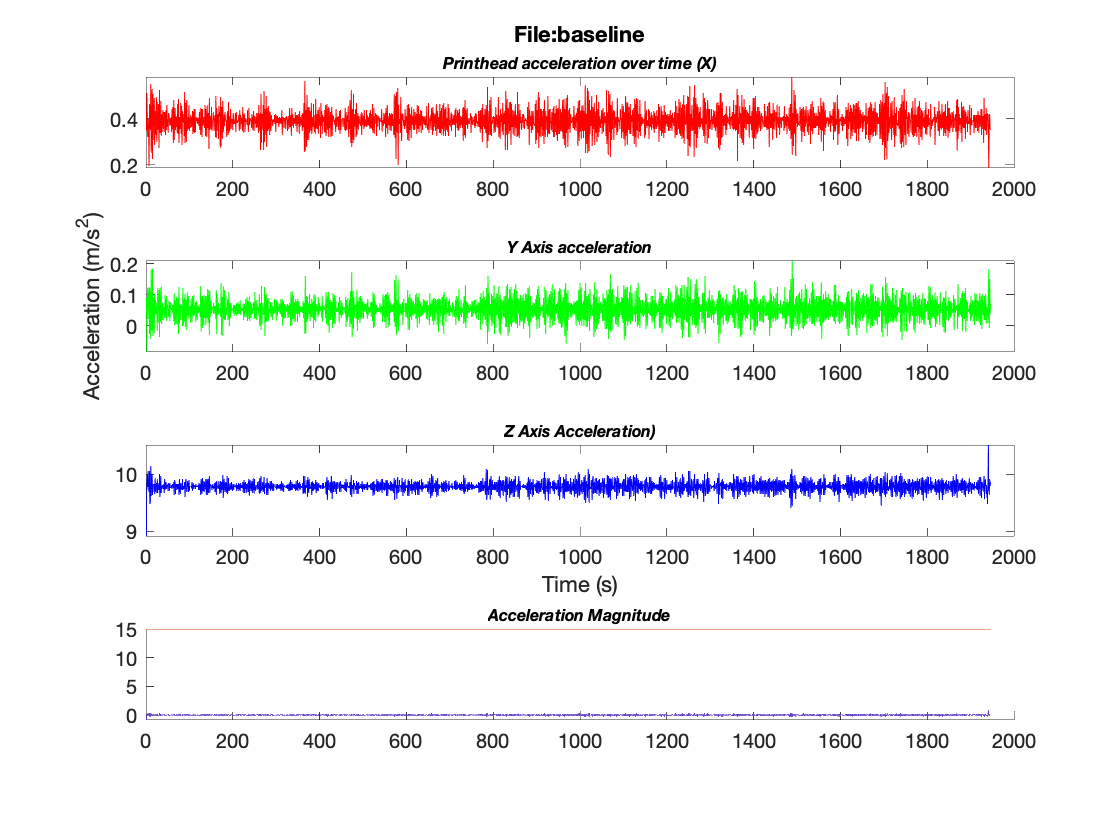

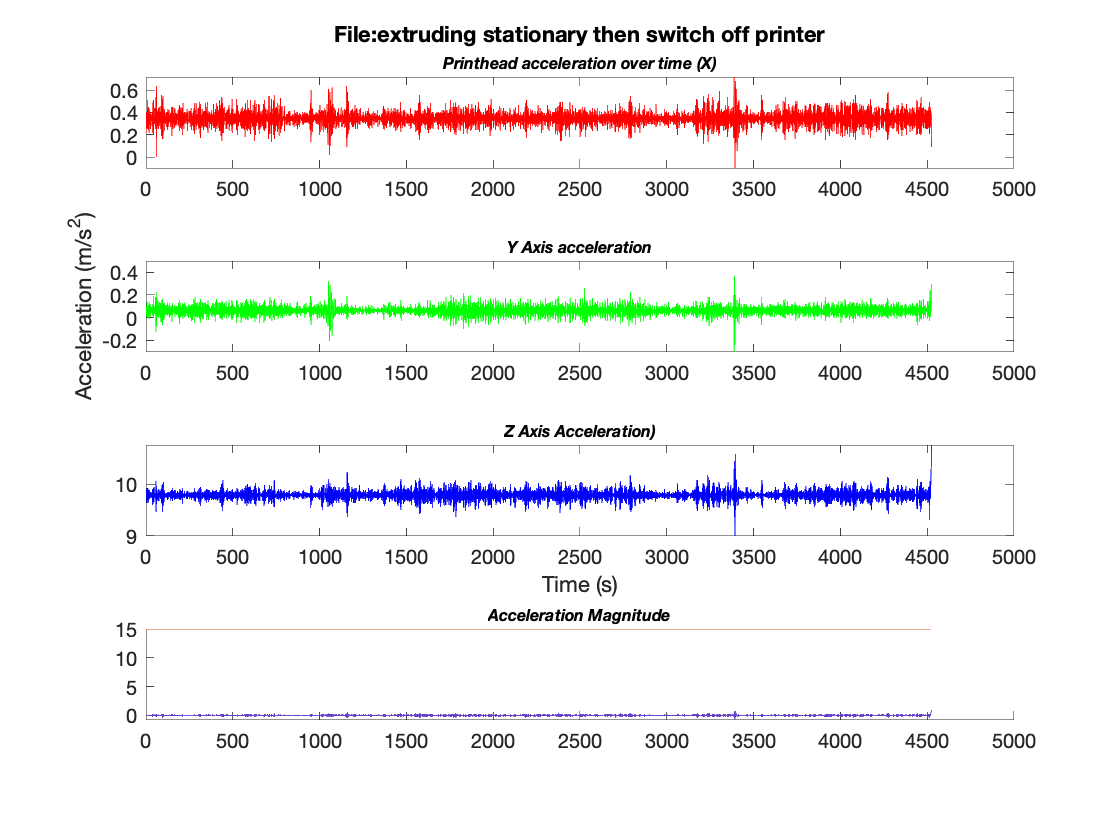

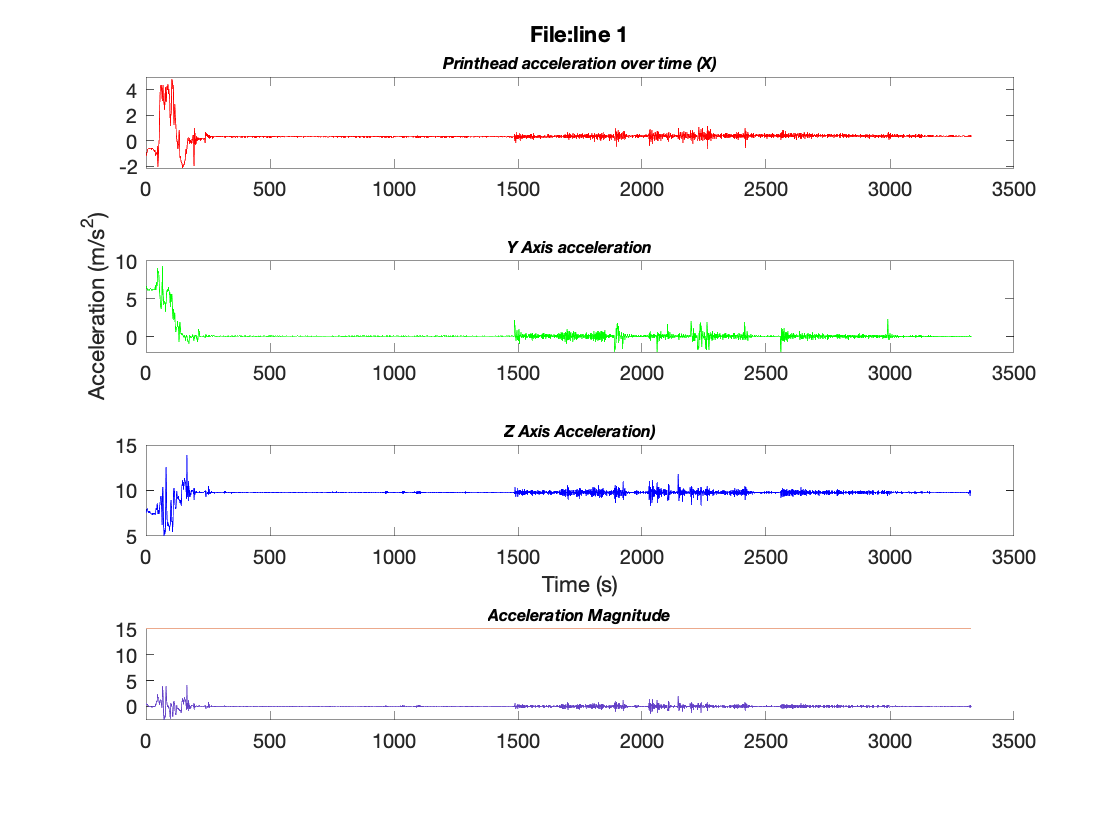

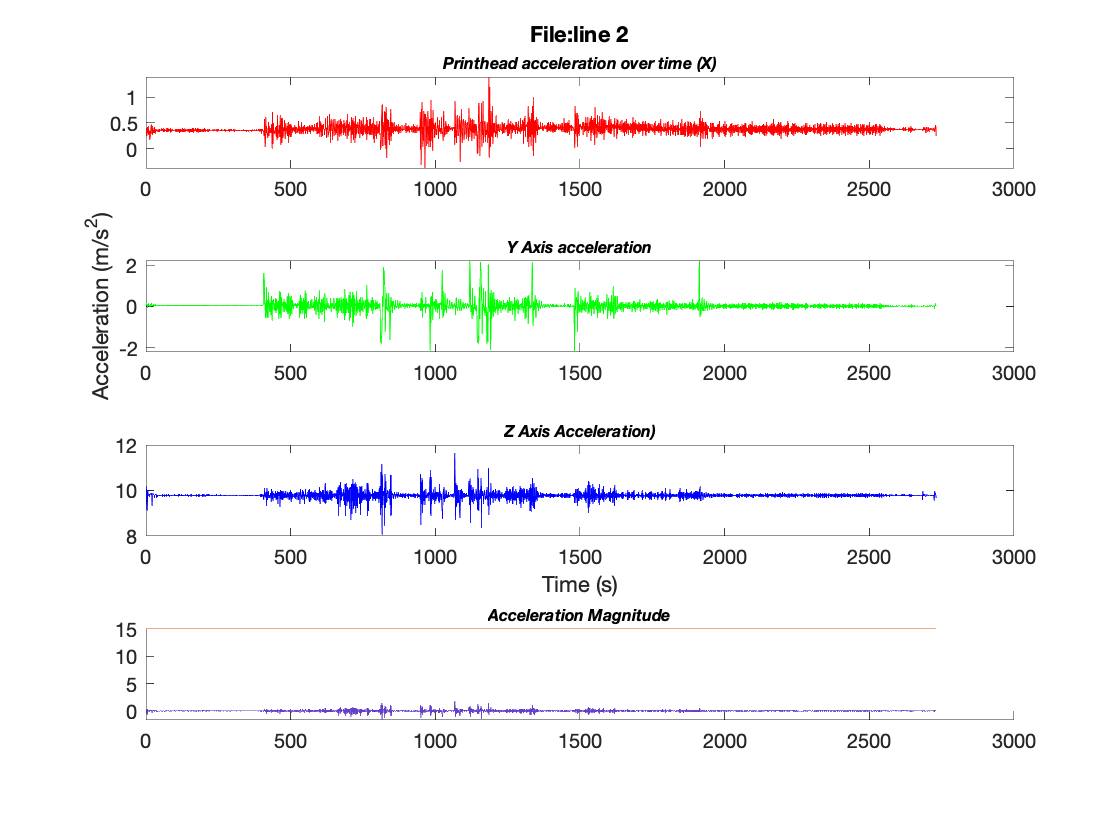

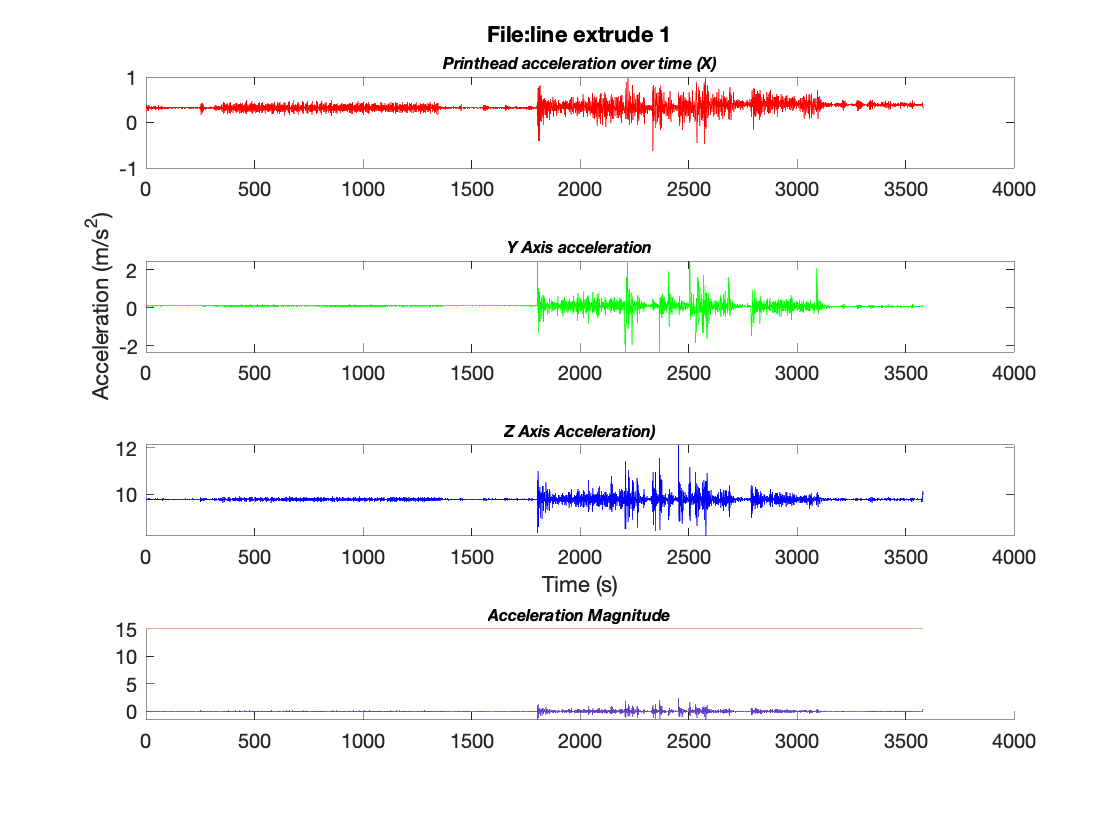

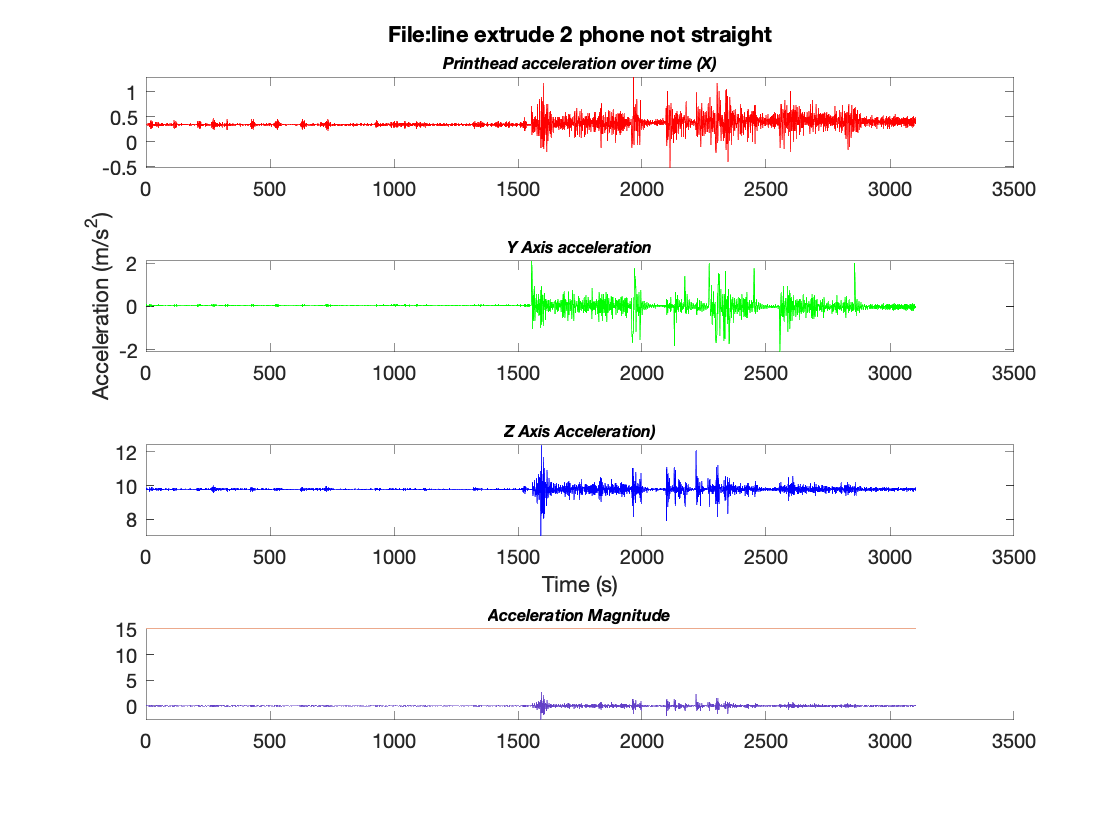

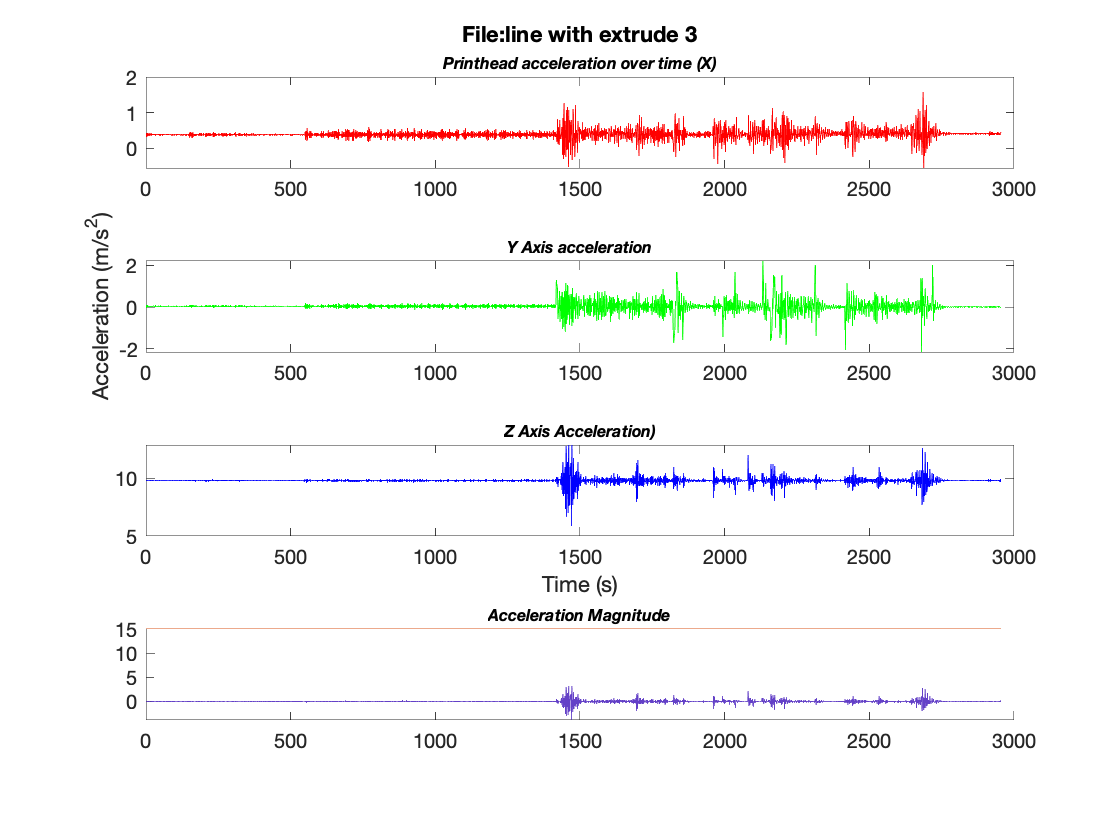

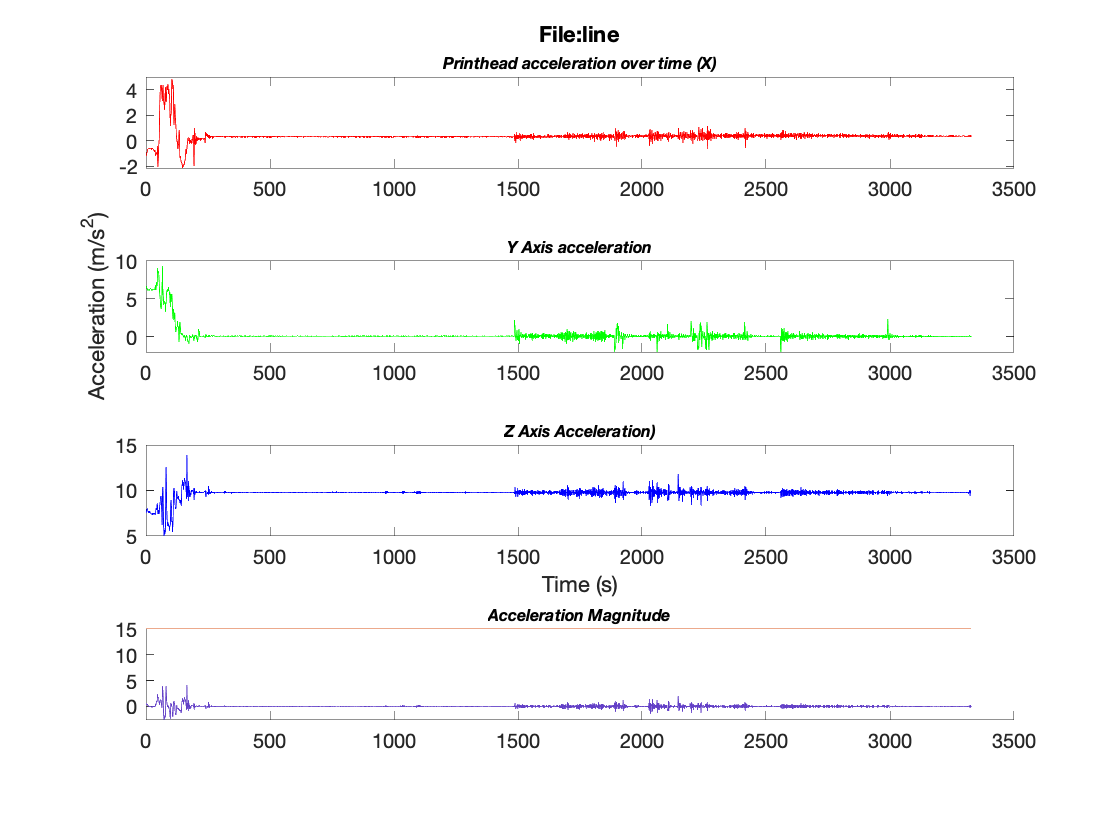

tic
for k = 1:length(mydata)
    sample = mydata(k);
    Acceleration = sample{1}.Acceleration;
    figure()
    a = timetable2table(Acceleration);
    accelData = [a.X a.Y a.Z]';
    
    subplot(4,1,1);
    plot(accelData(1,:), 'r')
    title({strcat('File: ',sample{1}.Source(1:end-4));"\fontsize{8}\itPrinthead acceleration over time (X)"})
    
    subplot(4,1,2);
    plot(accelData(2,:), 'g')
    title("\fontsize{8}\itY Axis acceleration")
    ylabel("Acceleration (m/s^2)")
    
    subplot(4,1,3);
    plot(accelData(3,:), 'b')
    title("\fontsize{8}\itZ Axis Acceleration)")
    xlabel("Time (s)")
    
    subplot(4,1,4);
    accelData = [a.X a.Y a.Z]';
    x = vecnorm(accelData);
    x = x - mean(x);
    hold on;
    plot(x, 'Color', [99, 64, 199]./255)
    title("\fontsize{8}\itAcceleration Magnitude")
    plot([0 length(x)], [15 15])
end

toc

Elapsed time is 1.955929 seconds.


## Run Simple Success Analysis

tic
for k = 1:length(mydata)
    sample = mydata(k);
    Acceleration = sample{1}.Acceleration;
    figure()
    a = timetable2table(Acceleration);
    accelData = [a.X a.Y a.Z]';
    subplot(3,1,1);
    plot(accelData(1,:))
    title("Printhead acceleration over time (X)")
    title({strcat('File: ',sample{1}.Source(1:end-4));"\fontsize{8}\itPrinthead acceleration over time (X)"})
    subplot(3,1,2);
    plot(accelData(2,:))
    title("\fontsize{8}\itY Axis acceleration")
    ylabel("Amplitude")
    subplot(3,1,3);
    plot(accelData(3,:))
    title("\fontsize{8}\itZ Axis Acceleration)")
    xlabel("Time (s)")
end
toc